## Test file to experiment with getting a good visual fit with log-normal distribution



% Clear any old data
clc;
clear variables;
close all;

% Load data
T = readtable('20200930_aerotrak.xlsx');


opTime = T.DateAndTime;
location = T.Location;
sampleTime = T.SampleTime;
avSampleTime = mode(sampleTime); % assumes sample time is not changed during operation, but excludes partial samples


% Sync times from different clocks as per the video
obsCamTime_endo = datetime(2020,9,30,11,09,55);
endoscopeTime = datetime(2020,9,30,11,24,20);

obsCamTime_aerotrak = datetime(2020,9,30,11,10,01);
aerotrakTime = datetime(2020,9,30,11,22,33) + seconds(avSampleTime); %Aerotrak time is the time at the start of the sample

aeroOffsetTime = aerotrakTime - obsCamTime_aerotrak;
endoOffsetTime = endoscopeTime - obsCamTime_endo;

opTime = opTime - aeroOffsetTime;

startTime = datetime(2020,9,30,11,20,00);
endTime = datetime(2020,9,30,12,50,00);

tValid = isbetween(opTime,startTime,endTime);
tValid = tValid & strcmpi(location,'Location01');

T = T(tValid,:);
T = T(1:end-1,:); % remove last count as it is likely partial

opTime2 = T.DateAndTime - aeroOffsetTime;
airVol = T.Volume_L_;

% Get a background reading
bgStartTime = datetime(2020,9,30,11,21,00);
bgEndTime = datetime(2020,9,30,11,25,00);
bgValid = isbetween(opTime2,bgStartTime,bgEndTime);

% Now get the particle 'diameters' representing the edges of the counting
% bins
maxDiameter = 25; % in microns - this is from the spec sheet
diameters = [T.Ch1Size__m_(1),T.Ch2Size__m_(1),T.Ch3Size__m_(1),T.Ch4Size__m_(1),T.Ch5Size__m_(1),T.Ch6Size__m_(1), maxDiameter];
diameters_av = (diameters(1:6)+diameters(2:7))/2; % Mean diameter in each bin


% The actual counts in each bin
data = [T.Ch1Diff___,T.Ch2Diff___,T.Ch3Diff___,T.Ch4Diff___,T.Ch5Diff___,T.Ch6Diff___];
data = data./repmat(airVol,1,size(data,2)) * 1000; %Because volume is liters so times by 1000 to get to m^3


% Convert counts to volumes
vols = 4/3*pi*(diameters_av/2).^3 * (1e-6)^3;

bin_sizes = diameters(2:7) - diameters(1:6);
log_bin_sizes = log(diameters(2:7)) - log(diameters(1:6));

data_v = data .* repmat(vols,size(data,1),1);

% Densities so that a probability density approach can be used
data_v_density = data_v ./ repmat(bin_sizes,size(data,1),1);
data_density = data ./ repmat(bin_sizes,size(data,1),1);

% Get a background reading
bgStartTime = datetime(2020,9,30,11,21,00);
bgEndTime = datetime(2020,9,30,11,23,00);
bgValid = isbetween(opTime2,bgStartTime,bgEndTime);
bg_density = data_density(bgValid,:);


### Now plot the data and superimpose a log-normal distribution


densities = mean(data_density(:,:),1)

densities = 	1.0e+06 *

    2.9608    0.4312    0.0424    0.0032    0.0005    0.0002


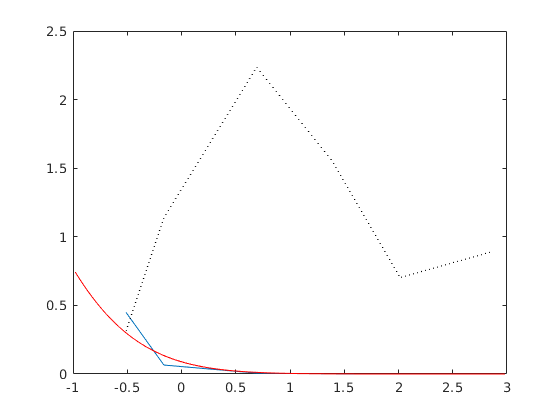


mu = -1.8;
sigma = 1.06;
scale = 6600000;

plotDiams = exp(linspace(-1,3,100));
plotDiams_av = 0.5*(plotDiams(1:end-1) + plotDiams(2:end));
plotBinSizes = (plotDiams(2:end) - plotDiams(1:end-1));

plot(log(diameters_av),(densities/scale));
hold on;
%plot(log(diameters_av),(logncdf(diameters(2:7),mu,sigma) - logncdf(diameters(1:6),mu,sigma))./binSizes,'r-');
plot(log(plotDiams_av),((logncdf(plotDiams(2:end),mu,sigma) - logncdf(plotDiams(1:end-1),mu,sigma))./plotBinSizes),'r-');

err = (densities/scale) - ((logncdf(diameters(2:end),mu,sigma) - logncdf(diameters(1:end-1),mu,sigma))./bin_sizes);
err = abs(err)./(densities/scale);
plot(log(diameters_av), err, 'k:')
hold off;

pause(0.01)

### Bimodal distribution

Using the log probabilities $P_{bg}$ and $P_{fg}$:


$$e^{P_{bg}} + we^{P_{fg}} = e^{P_{bg}}\left(1+we^{P_{fg}- P_{bg}}\right)$$



$$\log \left( e^{P_{fg}}\left(1+we^{P_{bg}- P_{fg}}\right) \right) = P_{fg} + \log(1+we^{P_{bg}- P_{fg}})$$
